clear
clearvars
clc

%LOAD DATA
dates = datetime(2022:-1:2013, 1, 1);
Years_row = year(dates);
Years_col=Years_row';
Years_col = num2str(Years_col);
Years_col = cellstr(Years_col);

%Inputted in columns
filename = "Data - National.xlsx";

DataI = readmatrix(filename,"Sheet","Innovation");
I1=DataI(5:14,12);
DataS = readmatrix(filename,"Sheet", "Stability");
S1=DataS(5:21,14);

X=I1

X =     8.8500
    8.1167
    6.3500
    6.2333
    6.1717
    6.6417
    8.4500
   10.7867
   12.7600
   11.5033


Y=S1(1:10)

Y =    53.7500
   54.6250
   55.2126
   56.7500
   58.2981
   59.6250
   60.0000
   61.2500
   61.1250
   62.0000


%PRESENT DATA
dx=0.2; dy=0.15;
F1=figure(1);
scatter(X,Y)
text(X+dx, Y+dy, Years_col,'FontSize',10);
title('Relationship between Innovation and Instability in Kazakhstan')
xlabel('Innovation Output Aggregate Score (%)') 
ylabel('Instability Aggregate Score (%)') 

xlim([58 72])
ylim([52 64])

%Converting factor variables from continuous to nominal data for ANOVA
%Where 1 is least, 3 is most 
 
X_edges=[min(X) min(X)+(1/3.*(max(X)-min(X))) min(X)+(2/3.*(max(X)-min(X))) max(X)];
Y_edges=[min(Y) min(Y)+(1/3.*(max(Y)-min(Y))) min(Y)+(2/3.*(max(Y)-min(Y))) max(Y)];
X_categories = discretize(X,X_edges);
Y_categories = discretize(Y,Y_edges);

%Converting to rows for ANOVA
X=X';
Y=Y';
X_categories = X_categories';
Y_categories = Y_categories';

%Running ANOVA
disp('Relationship test between Innovation and Instability')

Relationship test between Innovation and Instability


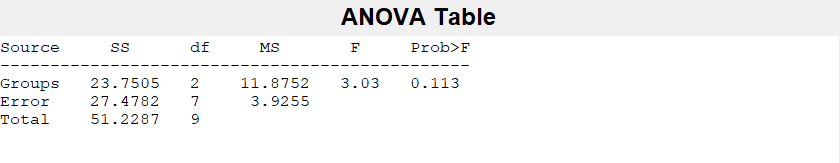

[p_1]=anova1(X, Y_categories);

disp('Relationship test between Instability and Innovation')

Relationship test between Instability and Innovation


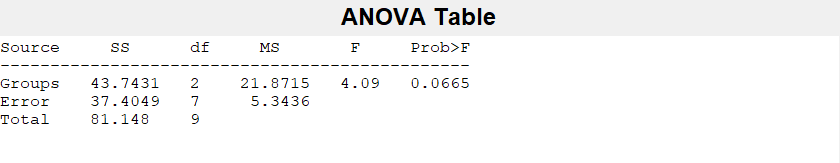

[p_2]=anova1(Y, X_categories);


%Converting to columns for correlation
X = X.';
Y = Y.';

%Running correlation calcs
SpearmanCoefficientYvX = corr(Y, X, 'type', 'Spearman', 'Rows','complete')

SpearmanCoefficientYvX = 0.5394

KendallCoefficientYvX = corr(Y, X, 'type', 'Kendall', 'Rows','complete')

KendallCoefficientYvX = 0.3333

PearsonCoefficientYvX = corr(Y, X, 'type', 'Pearson', 'Rows','complete')

PearsonCoefficientYvX = 0.5793

%RESULTS TABLE

column_names={'ANOVA variable',  'ANOVA variable (reverse direction)',  'SpearmanCoefficient', 'KendallCoefficient', 'PearsonCoefficient'};
row_names={'XvsY'};
values= {p_1, p_2, SpearmanCoefficientYvX, KendallCoefficientYvX, PearsonCoefficientYvX};
T=cell2table(values, 'RowNames', row_names, 'VariableNames', column_names)

T = 1×5 table
            ANOVA variable    ANOVA variable (reverse direction)    SpearmanCoefficient    KendallCoefficient    PearsonCoefficient
            ______________    __________________________________    ___________________    __________________    __________________

    XvsY       0.11302                     0.066493                       0.53939               0.33333               0.57926      
